# Editable Popup with Button

## Create the widget

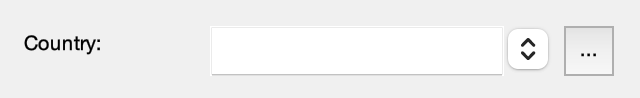

Error using matlab.ui.control.WebComponent/set
Functionality not supported with figures created with the uifigure function.

Error in uiw.mixin.HasContainer/onStyleChanged (line 100)
                    set(hAll( isprop(hAll,'FontUnits') ),...

Error in 

% The EditablePopupWithButton is a EditablePopup widget that just adds a
% button next to it. The button will trigger the Callback, however the
% programmer must decide what should happen when the button is pressed.

f = figure(...
    'Toolbar','none',...
    'MenuBar','none',...
    'NumberTitle','off',...
    'Units','pixels',...
    'Position',[100 100 320 49]);
movegui(f,[100 -100])

w = uiw.widget.EditablePopupWithButton(...
    'Parent',f,...
    'Items',{'USA','Canada','Mexico'},...
    'SelectedIndex',2,...
    'Value','France',...
    'Callback',@(h,e)disp(e.Interaction),...
    'Callback',@(h,e)disp(e),...
    'Label','Country:',...
    'LabelLocation','left',...
    'LabelWidth',90,...
    'Padding',2,... %Add some padding around the widget
    'Units','pixels',...
    'Position',[10 10 300 29]);

## Toggle the button visibility

w.ButtonVisible = false;

## Restore the button

w.ButtonVisible = true;